# 

## MATLAB Fundamentals: Tutorial 01, Exercise 03

### August 2023

# 3. Program Structures  

Program structures are an important part of MATLAB. In this exercise, you will learn how to implement a control flow for your program, with each question implementing a portion of your function. You shall control the execution of the code by using conditional statements and loops. 

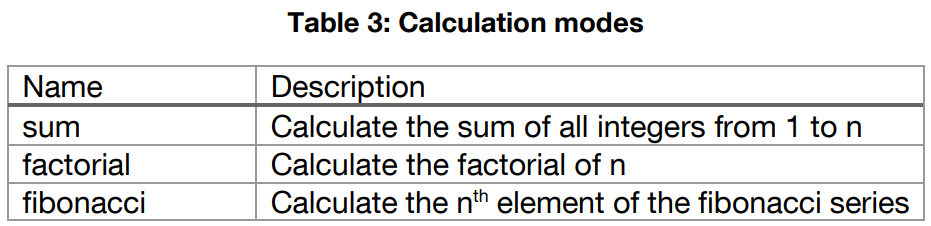

**Exercise**

(1)    Create a function (in a `.m` file) called `myFunction.m`, and try calling it in the code section below. Pay attention to the output of the function, in particular the number of them. What should you type to have access to all of the outputs ?

function [sumResult,factorialResult,fibonacciResult] = myFunction(n)

sumResult = sum(1:n);

factorialResult = factorial(n);

if n <= 0
    error('Input n must be a positive integer for fibonacci calculation.');
    elseif n == 1
        fibonacciResult = 0;
    elseif n == 2
        fibonacciResult = 1;
    else
        fib = [0, 1];
        for i = 3:n
            fib(i) = fib(i-1) + fib(i-2);
        end
        fibonacciResult = fib(n);
end

end

### *Hint: *Note that the name of a function and the file containing it must coincide.

(2)    Modify `myFunction.m`'s default signature so that it takes an integer as input, and returns an integer. You may want to test it before moving further, for example by having it display the input you give it.

function output = myFunction(input)
    output = input * 2;
end

(3)    We want all three computations of Table 3 performed by a single function, `myFunction.m`. Use the `input` command to retrieve via user `string` input the desired computation, and an `if` statement to display the description that belongs to the user’s choice in the command window. You may test your code in the section below before implementing it in your function.

function result = myFunction(n)
    % User enter the caculation mode into 'caculationMode'
    caculationMode = input('Please type in which caculation you want (sum, factorial, fibonacci): ', 's');
    
    % Perform the calculation based on the caculationMode
    if strcmp(caculationMode, 'sum')
        disp('Calculate the sum of all integers from 1 to n:');
        result = sum(1:n);  % Sum of integers from 1 to n
        
    elseif strcmp(caculationMode, 'factorial')
        disp('Calculate the factorial of n:');
        result = factorial(n);  % Factorial of n
        
    elseif strcmp(caculationMode, 'fibonacci')
        disp('Calculate the nth element of the Fibonacci series:');
        
        % Calculate the nth Fibonacci number
        if n <= 0
            error('Input n must be a positive integer.');
        elseif n == 1
            result = 0;
        elseif n == 2
            result = 1;
        else
            fib = [0, 1];
            for i = 3:n
                fib(i) = fib(i-1) + fib(i-2);
            end
            result = fib(n);
        end
        
    else
        error('Invalid mode. Re-enter "sum", "factorial", or "fibonacci".');
    end
    
    % Display the result
    disp(['Result: ', result]);
end

What happens if the string entered by the user is not recognized ? Modify your code to handle that case of figure with an error message.

(4)    Repeat question (3) using a `switch` statement. Check the MATLAB documentation for the exact syntax.

(5)    We implement the sum computation. Use a `for`-loop to determine the sum of all integers from 1 to n. Set n to 100 and test your program.

(6)    Use a `while`-loop to implement the factorial calculation.

(7)    Use either loop statements to implement the Fibonacci series. It is defined as follows:


$$a_0 = 0 \\
a_1 = 1 \\
\forall n \geq 2, \; a_n = a_{n-1} + a_{n-2}$$


(8)    Calculation time can be long for large numbers of n. Using the `tic` and `toc` commands, implement a check of the calculation time and abort the loop if a maximal calculation time is exceeded. Increase n and reduce the maximal calculation time until it is exceeded to test this out.

Technische Universität München – Lehrstuhl für Flugsystemdynamik – MATLAB Fundamentals: Tutorial 01 – August 2023